# 最短路径

引用：https://www.bilibili.com/video/BV1Rq4y1S7S8?p=29&spm_id_from=pageDriver

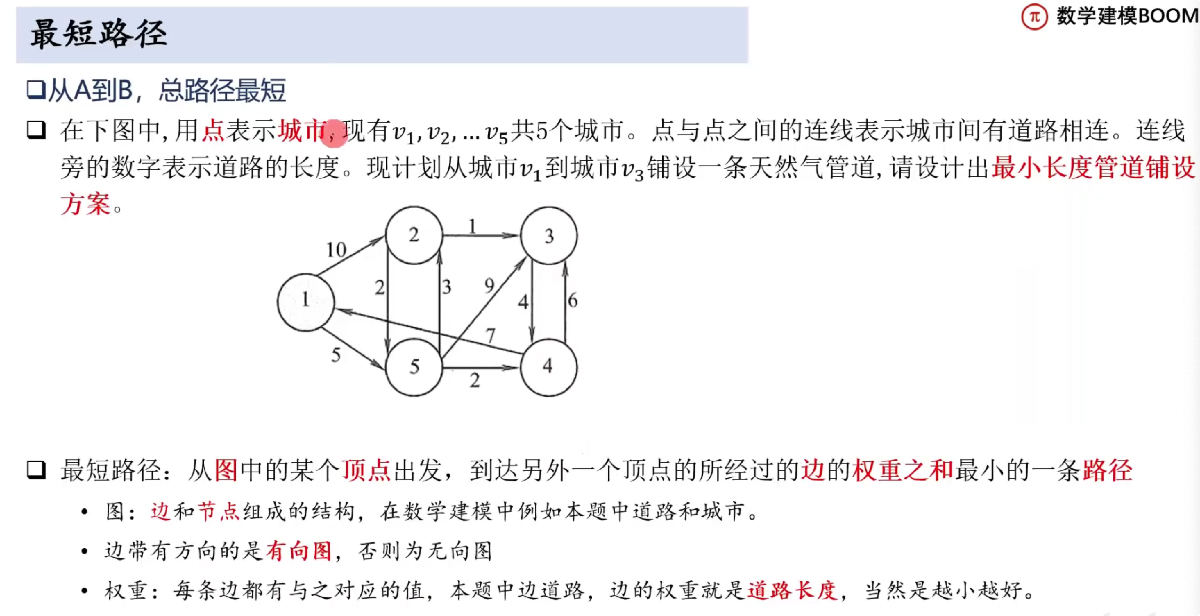

## 1. 稀疏矩阵和权值

`sparse()` - 生成稀疏矩阵，也就是除了注明的几个元素之外其他的都是 0

`W` -  表示每条稀疏矩阵对应路径权值

`DG` - 稀疏矩阵和权值

W = [10 5 2 1 4 6 7 3 9 2]

W =     10     5     2     1     4     6     7     3     9     2



DG = sparse( ...
    [1 1 2 2 3 4 4 5 5 5], ...
    [2 5 5 3 4 3 1 2 3 4], ...
    W)

DG =    (4,1)        7
   (1,2)       10
   (5,2)        3
   (2,3)        1
   (4,3)        6
   (5,3)        9
   (3,4)        4
   (5,4)        2
   (1,5)        5
   (2,5)        2


## 2.【函数】求最短路径：

[dist, path, pred] = graphshortestpath(稀疏矩阵和权值, 起始节点, 结束节点)

dist - 最短路径的值

path - 最短路径经过的节点

pred - 

[dist, path, pred] = graphshortestpath(DG, 1, 3)

dist = 9

path =      1     5     2     3


pred =      0     5     2     5     1


biograph 生成图对象

view 显示该图

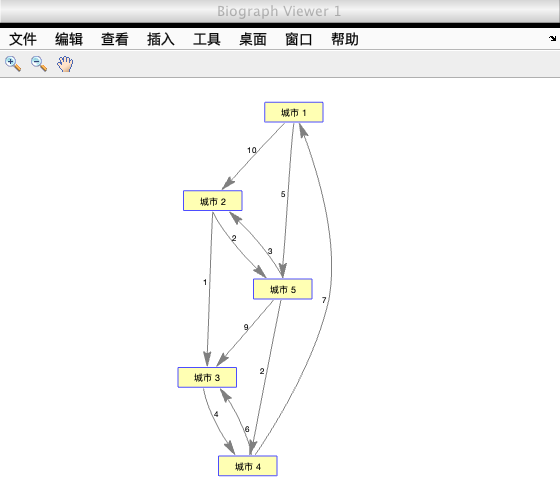

Biograph object with 5 nodes and 10 edges.


point_name = ["城市 1", "城市 2", "城市 3", "城市 4", "城市 5"];
h = view(biograph(DG, point_name, "ShowWeights", "on"))

将最短路径的节点和边缘标记为红色并增加线宽：

`getedgesbynodeidt` 得到图h的指定边的句柄

- 第一个参数是图

- 第二个是边的出点

- 第三个是边的入点句柄确保能找到对应的东西

get 查询图的属性，h. Nodes(path)，'ID' 得到图h中最短路径的

set函数设置图形属性

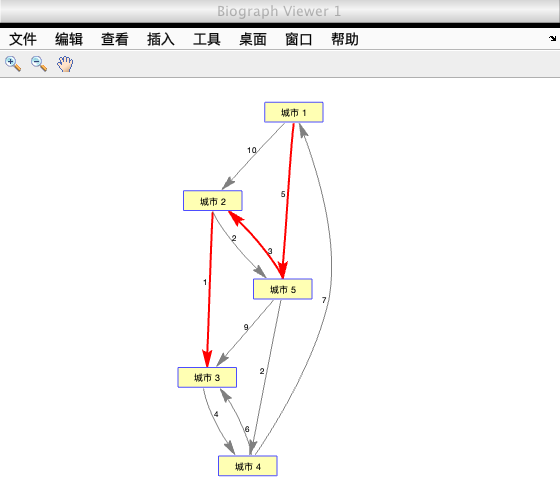

edges = getedgesbynodeid(h, get(h.Nodes(path), 'ID'));
set(edges, 'LineColor', [1 0 0])  % 第二个参数是：RGB 数值
set(edges, 'LineWidth', 2)